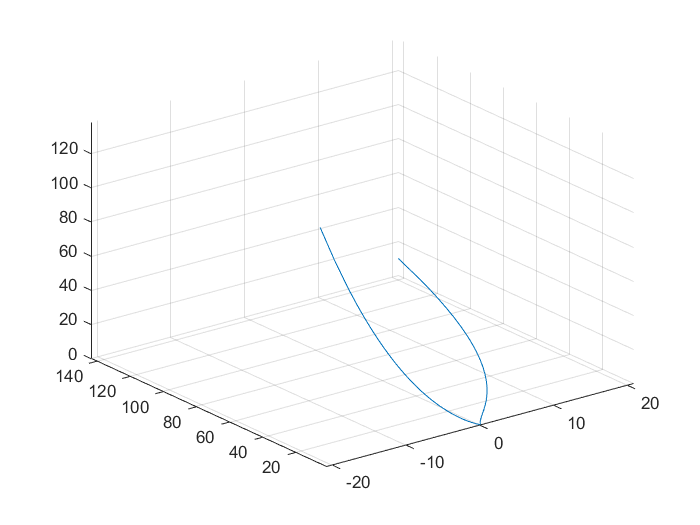

syms t

a = [t exp(t) exp(-t)]; %Definir vector de aceleración

v = int(a,t); %Integrando la aceleración para obtener vector velocidad
cv = [0 0 1]; %c de velocidad = [valorI valorJ valorK]
cv = cv-subs(v,t,0); %resta v(0) para obtener el valor de c en la formulad e velocidad
v = v+cv; %Al vector de velocidad le sumamos su velocidad inicial

s = int(v,t); %Integrando la velocidad para obtener el vector de posición
cs = [0 1 1]; %c de posición = [valorI valorJ valorK]
cs = cs-subs(s,t,0); %resta s(0) para obtener el valor de c en la formulad e posición
s = s+cs; %Al vector de posición le sumamos su posición inicial

x = s(1); %asigna a x el indice 1 del vector posición
y = s(2); %asigna a y el indice 2 del vector posición
z = s(3); %asigna a z el indice 3 del vector posición

fplot3(x,y,z); %Grafica en 3 dimensiones el vector posición